# Allan Variance Analysis

This was part of "q_data_processing.mlx", but after I completed the autocorrellation section the Allan Variance section just quit working.  Not sure what's going on with that, so now the allanvar piece gets its own live script.  

% Let's ensure we are working with the correct data
close all
clear all
clc
load('VN200_accel_gyro_8_hr.mat')

% Some convienent vectors for plotting
axis_str = ['X', 'Y', 'Z'];
clr_str = ['r', 'g', 'b'];
 
% % Detrend Data
% accel = detrend(accel);
% gyro = detrend(gyro);


## Allan Variance Plots

Using the MATLAB provided function 'allanvar'

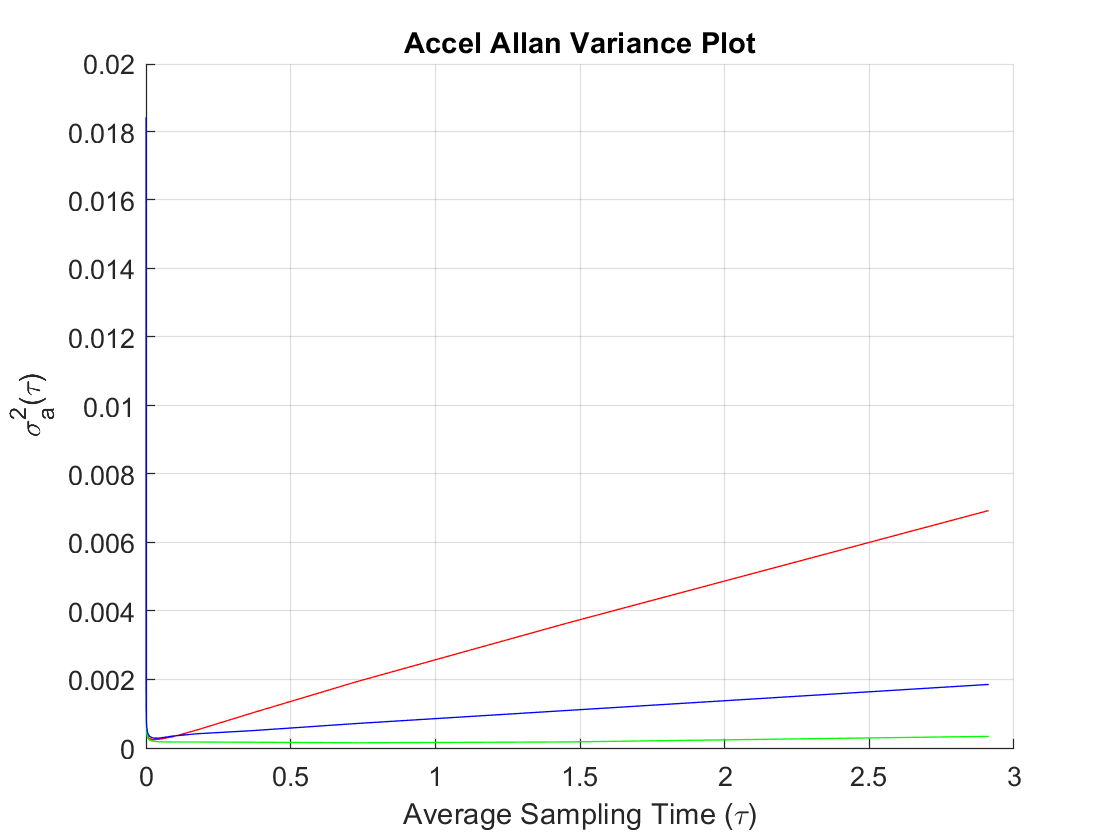

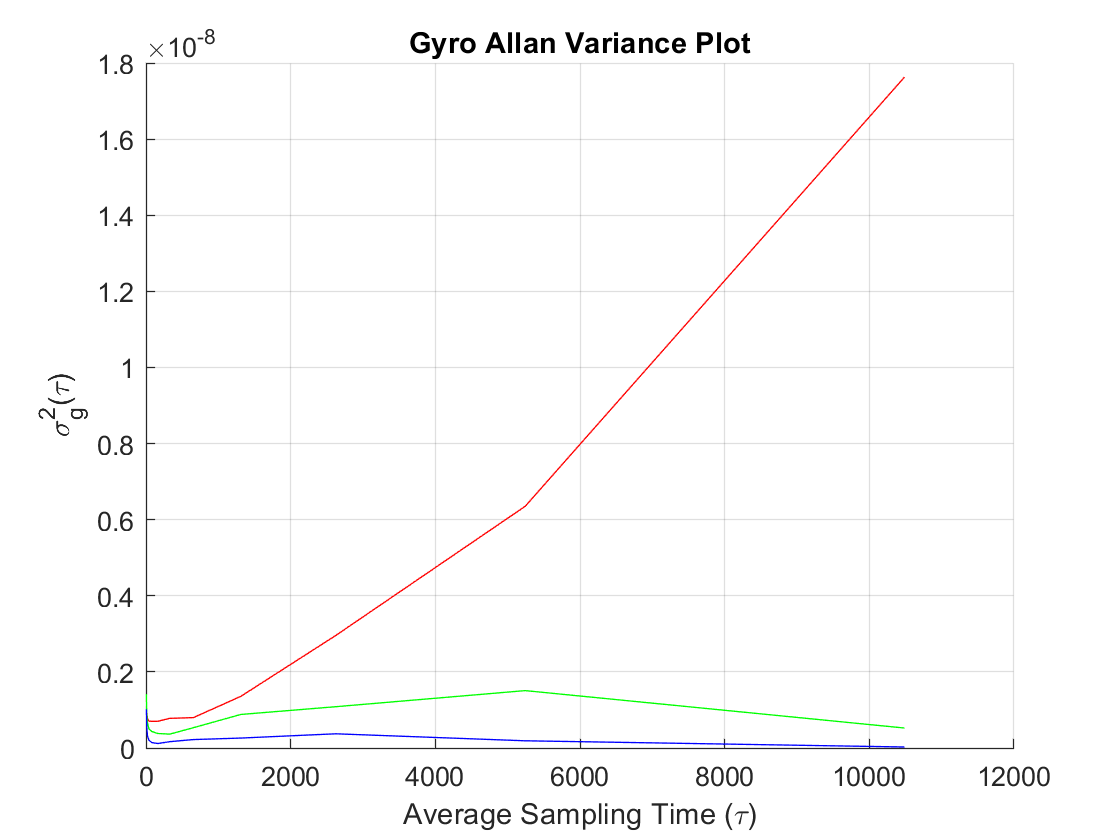

 % Create the Allen Var Data
 m = 2 .^ (9 : 20);
 
 for ii = 1 : 3
     
     % Allan Variance for Accel
     [avar, tau] = allanvar(accel(:,ii), 'octave', Fs);
     
     % Plot Accel Allan Variance Plots
     figure(1)
     hold on
     loglog(tau/3600, sqrt(avar), clr_str(ii))
     title('Accel Allan Variance Plot')
     xlabel('Average Sampling Time (\tau)')
     ylabel('\sigma_a^2(\tau)')
     grid on
     hold off
     
     % Allan Variance for Gyro
     [avar, tau] = allanvar(gyro(:,ii), m, Fs);
     
     % Plot Gyro Allan Variance Plots
     figure(2)
     hold on
     loglog(tau, avar, clr_str(ii))
     title('Gyro Allan Variance Plot')
     xlabel('Average Sampling Time (\tau)')
     ylabel('\sigma_g^2(\tau)')
     grid on
     hold off

 end